% Example_5_2.m
%
% This is Example 5.2 from the paper 'Geometric modelling of 
% polycrystalline materials: Laguerre tessellations and periodic 
% semi-discrete optimal transport' by D.P. Bourne, M. Pearce & S.M. Roper.
%
% In this example we monitor the number of Newton iterations and 
% backtracking steps in 100 draws of 100,000 log-normally distributed 
% grain volumes.

clear

## Specify box dimensions

bx=[1,1,1];

## Specify periodicity

periodic=true;

## Specify maximal percentage error

percent_tol=1;

## Specify number of seeds (grains)

n=[1000]; % Set n=[100000] to reproduce example from paper 
nn=length(n);

## Specify number of experiments

nexp=100;

## Log-normal backtracking

% Parameters in log-normal distribution
ln_mean=1; % mean
std_dev=0.35; % standard deviation
sigma=sqrt((log(1+(std_dev/ln_mean)^2))); % log-normal parameter sigma
mu=-0.5*sigma^2+log(ln_mean); % log-normal parameter mu

disp('Log-normal')

Log-normal


for idx_n=1:nn
    
    % For each number of seeds
    disp(sprintf('Calculating run times for n = %d',n(idx_n)));
    
    % Initial guess is always w=0
    w_0=zeros(n(idx_n),1);
    
    for idx_exp=1:nexp
        % For each experiment
        fprintf('\t Experiment number %d',idx_exp);
        
        % Seed locations
        X=rand(n(idx_n),3);

        % Compute target volumes: 
        % Draw radii from log-normal distribution
        rad=lognrnd(mu,sigma,n(idx_n),1); 
        % Calculate the corresponding grain volumes 
        % (we don't need the factor 4pi/3 as we'll be renormalising)
        target_vols=rad.^3;
        % Normalise the volumes so that they add to the volume of the box
        target_vols=target_vols*prod(bx)/sum(target_vols); % target volumes of the grains
        
        % Store the X and target_vols in case later interrogation is required
        X_ln{idx_n,idx_exp}=X;
        tv_ln{idx_n,idx_exp}=target_vols;

        % Time the damped Newton method
        tic
        [w,max_percent_err,actual_vols,EXITFLAG,back_track_steps,newton_step_errors,w_steps] = SDOT_damped_Newton_diagnostic(w_0,X,target_vols,bx,periodic,percent_tol);
        t=toc;
        
        fprintf(' : completed in %f\n',t);
        
        % Store the solution for w
        w_ln{idx_n,idx_exp}=w;

        % Store the deails of each Newton iteration and the error after each Newton iteration
        runtime_ln(idx_n,idx_exp)=t; % run times 
        back_track_ln{idx_n,idx_exp}=back_track_steps; % number of backtracking steps
        newton_errors_ln{idx_n,idx_exp}=newton_step_errors; % volume errors
    end

    disp(sprintf('Average run time %f',mean(runtime_ln(idx_n,:)')));
end

Calculating run times for n = 1000


	 Experiment number 1

 : completed in 1.042100


	 Experiment number 2

 : completed in 0.990089


	 Experiment number 3

 : completed in 1.192071


	 Experiment number 4

 : completed in 1.077584


	 Experiment number 5

 : completed in 1.002131


	 Experiment number 6

 : completed in 1.043316


	 Experiment number 7

 : completed in 1.304515


	 Experiment number 8

 : completed in 1.396532


	 Experiment number 9

 : completed in 0.996712


	 Experiment number 10

 : completed in 1.035925


	 Experiment number 11

 : completed in 1.059413


	 Experiment number 12

 : completed in 1.232525


	 Experiment number 13

 : completed in 1.404224


	 Experiment number 14

 : completed in 0.889686


	 Experiment number 15

 : completed in 1.304110


	 Experiment number 16

 : completed in 1.019343


	 Experiment number 17

 : completed in 1.265257


	 Experiment number 18

 : completed in 1.125614


	 Experiment number 19

 : completed in 1.064318


	 Experiment number 20

 : completed in 1.295671


	 Experiment number 21

 : completed in 1.077892


	 Experiment number 22

 : completed in 1.557409


	 Experiment number 23

 : completed in 1.203210


	 Experiment number 24

 : completed in 1.382126


	 Experiment number 25

 : completed in 1.233199


	 Experiment number 26

 : completed in 1.264140


	 Experiment number 27

 : completed in 1.603400


	 Experiment number 28

 : completed in 1.531639


	 Experiment number 29

 : completed in 1.256970


	 Experiment number 30

 : completed in 1.265272


	 Experiment number 31

 : completed in 1.310663


	 Experiment number 32

 : completed in 1.520637


	 Experiment number 33

 : completed in 1.152994


	 Experiment number 34

 : completed in 0.995557


	 Experiment number 35

 : completed in 1.249189


	 Experiment number 36

 : completed in 1.322670


	 Experiment number 37

 : completed in 1.529212


	 Experiment number 38

 : completed in 1.569904


	 Experiment number 39

 : completed in 1.168303


	 Experiment number 40

 : completed in 1.550462


	 Experiment number 41

 : completed in 1.232540


	 Experiment number 42

 : completed in 1.586489


	 Experiment number 43

 : completed in 1.515356


	 Experiment number 44

 : completed in 1.175128


	 Experiment number 45

 : completed in 1.445730


	 Experiment number 46

 : completed in 1.244150


	 Experiment number 47

 : completed in 1.283798


	 Experiment number 48

 : completed in 1.639055


	 Experiment number 49

 : completed in 1.198793


	 Experiment number 50

 : completed in 1.387115


	 Experiment number 51

 : completed in 1.511974


	 Experiment number 52

 : completed in 1.227046


	 Experiment number 53

 : completed in 1.309677


	 Experiment number 54

 : completed in 1.762916


	 Experiment number 55

 : completed in 1.363067


	 Experiment number 56

 : completed in 1.084791


	 Experiment number 57

 : completed in 1.648994


	 Experiment number 58

 : completed in 1.200732


	 Experiment number 59

 : completed in 1.436852


	 Experiment number 60

 : completed in 1.708129


	 Experiment number 61

 : completed in 1.669034


	 Experiment number 62

 : completed in 1.540095


	 Experiment number 63

 : completed in 1.222775


	 Experiment number 64

 : completed in 1.245343


	 Experiment number 65

 : completed in 1.704411


	 Experiment number 66

 : completed in 1.252242


	 Experiment number 67

 : completed in 1.486437


	 Experiment number 68

 : completed in 1.410086


	 Experiment number 69

 : completed in 1.571898


	 Experiment number 70

 : completed in 1.126115


	 Experiment number 71

 : completed in 1.433958


	 Experiment number 72

 : completed in 1.248139


	 Experiment number 73

 : completed in 1.196393


	 Experiment number 74

 : completed in 1.213115


	 Experiment number 75

 : completed in 1.178006


	 Experiment number 76

 : completed in 1.166810


	 Experiment number 77

 : completed in 1.174117


	 Experiment number 78

 : completed in 1.635863


	 Experiment number 79

 : completed in 1.369495


	 Experiment number 80

 : completed in 1.323882


	 Experiment number 81

 : completed in 1.582584


	 Experiment number 82

 : completed in 1.957933


	 Experiment number 83

 : completed in 1.841797


	 Experiment number 84

 : completed in 2.359346


	 Experiment number 85

 : completed in 2.492234


	 Experiment number 86

 : completed in 2.570375


	 Experiment number 87

 : completed in 2.938443


	 Experiment number 88

 : completed in 1.851986


	 Experiment number 89

 : completed in 1.864190


	 Experiment number 90

 : completed in 1.290329


	 Experiment number 91

 : completed in 1.235012


	 Experiment number 92

 : completed in 1.267284


	 Experiment number 93

 : completed in 1.152928


	 Experiment number 94

 : completed in 1.355644


	 Experiment number 95

 : completed in 1.202549


	 Experiment number 96

 : completed in 1.108274


	 Experiment number 97

 : completed in 1.196332


	 Experiment number 98

 : completed in 1.113747


	 Experiment number 99

 : completed in 1.214443


	 Experiment number 100

 : completed in 1.239828


Average run time 1.374518


## Plot the results

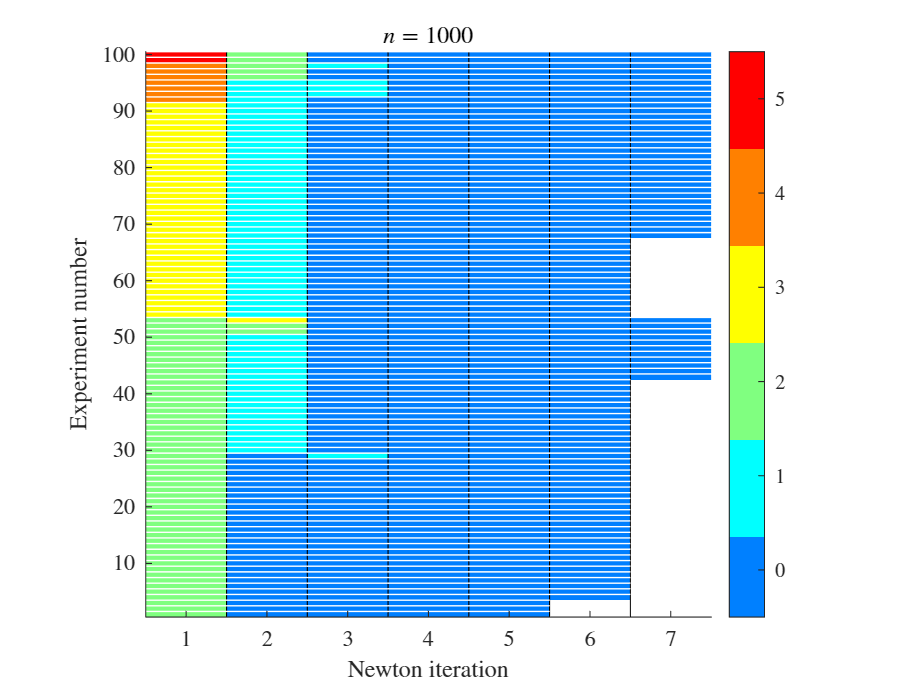

% Assume that n is a 1 x nn array of cell numbers
% Assume that back_track_ln is an nn x nexp cell array of backtracking information

[nn,nexp]=size(back_track_ln);

for k=1:nn
    back_track_exp=back_track_ln(k,:);

    % First find maximum number of Newton steps
    newt_steps=cellfun('length',back_track_exp);
    mns=max(newt_steps);
    data=-1*ones(nexp,mns);

    % Extract the data from the backtracking cell array
    for j=1:nexp
        data(j,1:length(back_track_exp{j}))=back_track_exp{j};
    end

    % Sort the data for ease of visualisation
    data=sortrows(data);

    % The maximum number of backtracking steps
    mbs=max(max(data));

    % Make a new figure, one for each number of cells
    figure(k)
    
    % Plot the number of backtracking steps
    image(1:mns,1:nexp,data,'CDataMapping','scaled')
    title(sprintf('$n=%d$',n(k)),'Interpreter','latex','Fontsize',12)

    % Make a discrete palette
    cmap=jet(mbs+2);
    % Make -1 correspond to white
    cmap(1,:)=[1 1 1];

    colormap(cmap);
    cbh=colorbar;
    ch=(mbs)/(mbs+1);
    cbh.Ticks=linspace(0.5*ch, mbs-0.5*ch, mbs+1) ; %Create 8 ticks from zero to 1
    cbh.TickLabels=num2cell(0:mbs);
    cbh.Limits=[0,mbs];
    xlabel('Newton iteration','Interpreter','latex','Fontsize',12)
    ylabel('Experiment number','Interpreter','latex','Fontsize',12)
    xlim([0.5,mns+0.5]);
    ylim([0.5,nexp+0.5]);

    set(gca,'YDir','normal','TickLabelInterpreter','latex','Fontsize',10,'box','off');
    set(gca,'XTickLabelMode','manual');
    set(gca,'XTickLabels',num2cell(1:mns));
    set(gca,'XTickMode','manual');
    set(gca,'XTick',1:mns);
    
    hold on
    for l=1:mns-1
        plot(0.5+[l l],[0.5,nexp+0.5],'k');
    end

    for l=1:nexp
        % Number of Newton steps
        ns=sum(data(l,:)>=0);
        plot([0 ns+0.5],0.5+[1 1]*l,'w','LineWidth',0.25);
    end
    hold off

    set(cbh,'TickLabelInterpreter','latex');
    axis square
    
end